# Custom Layers Example for Supported DSPC layer.

Example of using Custom layers to model a DSPC supportd bilayer.

Start by making the class and setting it to a custom layers type:

problem = project(name='oDSPC - Custom Layers', calcType='non polarised', model='custom layers', geometry='substrate/liquid', absorption=false);
problem.setUsePriors(true);

For a custom layers model, rather than being forced to define out layers as [Thick SLD Rough.... etc], we can parameterise however we like and then use a function to calculate the [d rho sigma] arrangement for each layer. So for example, if the volume of lipid tails are known (from the literature), then all we need is the Area per molecule, because then....

$d=\frac{V}{\textrm{APM}}$,

where d is the thickness and V is the volume.

Likewise, the SLD is


$$\rho =\frac{\sum_i n_i b_i }{V}$$


as usual.

In this folder there is a pre-prepared Matlab custom model for a DSPC on a Silicon substrate. We can display it here to see what we mean.....

type('DSPC_Custom_Bilayer')

function [output,sub_rough] = DSPC_Custom_Bilayer(params,bulk_in,bulk_out,contrast)
%CUSTOMBILAYER  RASCAL Custom Layer Model File.
%
%
% This file accepts 3 vectors containing the values for
% Params, bulk in and bulk out
% The final parameter is an index of the contrast being calculated
% The m-file should output a matrix of layer values, in the form..
% Output = [thick 1, SLD 1, Rough 1, Percent Hydration 1, Hydrate how 1
%           ....
%           thick n, SLD n, Rough n, Percent Hydration n, Hydration how n]
% The "hydrate how" parameter decides if the layer is hydrated with
% Bulk out or Bulk in phases. Set to 1 for Bulk out, zero for Bulk in.
% Alternatively, leave out hydration and just return..
% Output = [thick 1, SLD 1, Rough 1,
%           ....
%           thick n, SLD n, Rough n] };
% The second output parameter should be the substrate roughness

sub_rough = params(1);
oxide_thick = params(2);
oxide_hydration = params(3);
lipidAPM = params(4);
headHydration = params(5);


We need to add the parameters we are going to need to define the model (note that Substrate Roughness' always exists as parameter 1 as before, and that we are setting a Gaussian prior on Head Hydration here).

Parameters = {
    %       Name                min         val         max     fit? 
        {'Oxide thick',         5,          20,         60,     true   };
        {'Oxide Hydration'      0,          0.2,        0.5,    true   };
        {'Lipid APM'            45          55          65      true   };
        {'Head Hydration'       0           0.2         0.7     true   'gaussian'   0.3     0.03};
        {'Bilayer Hydration'    0           0.1         0.2     true   };
        {'Bilayer Roughness'    2           4           8       true   };
        {'Water Thickness'      0           2           10      true   };
        };
    
 problem.addParameterGroup(Parameters);
 problem.setParameter(1,'min',1,'max',10); % Change the substrate roughness limits

Need to add the relevant Bulk SLD's. Change the bulk in from air to silicon, and add two additional water contrasts:

% Change bulk in from air to silicon....
problem.setBulkIn(1,'name','Silicon','min',2.07e-6,'value',2.073e-6,'max',2.08e-6,'fit',false);

% Add two more values for bulk out....
problem.addBulkOut('SLD SMW',1e-6,2.073e-6,3e-6,true);
problem.addBulkOut('SLD H2O',-0.6e-6,-0.56e-6,-0.3e-6,true);

problem.setBulkOut(1,'fit',true,'min',5e-6);

Now add the datafiles. We have three datasets we need to consider - the bilayer against D2O, Silicon Matched water and H2O. Load these datafiles in and put them in the data block....

% Read in the datafiles
D2O_data = dlmread('c_PLP0016596.dat');
SMW_data = dlmread('c_PLP0016601.dat');
H2O_data = dlmread('c_PLP0016607.dat');

% Add the data to the project
problem.addData('Bilayer / D2O', D2O_data);
problem.addData('Bilayer / SMW', SMW_data);
problem.addData('Bilayer / H2O', H2O_data);

problem.setData(2,'dataRange',[0.013 0.37]);
problem.setData(3,'dataRange',[0.013 0.37]);
problem.setData(4,'dataRange',[0.013 0.37]);

Add the custom file to the project....                         

problem.addCustomFile('DSPC Model', 'customBilayer.m');

Also, add the relevant background parameters - one each for each contrast:

% Change the name of the existing parameters to refer to D2O
problem.setBacksPar(1,'name','Backs par D2O','fit',true,'min',1e-10,'max',1e-5,'val',1e-6);

% Add two new backs parameters for the other two..
problem.addBacksPar('Backs par SMW',1e-10,1e-6,1e-5,true);
problem.addBacksPar('Backs par H2O',1e-10,1e-6,1e-5,true);

% And add the two new constant backgrounds..
problem.addBackground('Background SMW','constant','Backs par SMW');
problem.addBackground('Background H2O','constant','Backs par H2O');


% And edit the other one....
problem.setBackgroundName(1,'Background D2O');
problem.setBackground(1,'value1','Backs par D2O');

% Finally modify some of the other parameters 

% Set the scalefactor...
problem.setScalefactor(1,'Value',1,'min',0.5,'max',2,'fit',true);


We need to use the data resolution (i.e. the fourch column of our datafiles). Do do this, we need to add a 'Data' resolution object to our resolutions table...

problem.addResolution('Data Resolution','data');

Now add the three contrasts as before:

% D2O contrast..
problem.addContrast('name','Bilayer / D2O',...
    'background','Background D2O',...
    'resolution','Data Resolution',...
    'scalefactor', 'Scalefactor 1',...
    'nbs', 'SLD D2O',...        % This is bulk out ('Nb Subs')
    'nba', 'Silicon',...        % This is bulk in ('Nb Air')
    'data', 'Bilayer / D2O');

% SMW contrast..
problem.addContrast('name','Bilayer / SMW',...
    'background','Background SMW',...
    'resolution','Data Resolution',...
    'scalefactor', 'Scalefactor 1',...
    'nbs', 'SLD SMW',...        % This is bulk out
    'nba', 'Silicon',...        % This is bulk in
    'data', 'Bilayer / SMW');

% SMW contrast..
problem.addContrast('name','Bilayer / H2O',...
    'background','Background H2O',...
    'resolution','Data Resolution',...
    'scalefactor', 'Scalefactor 1',...
    'nbs', 'SLD H2O',...        % This is bulk out
    'nba', 'Silicon',...        % This is bulk in
    'data', 'Bilayer / H2O');

This time, to set the model, we point to the custom file we've just added to the project.....

problem.setContrastModel(1,'DSPC Model');
problem.setContrastModel(2,'DSPC Model');
problem.setContrastModel(3,'DSPC Model');

Look at the complete model definition before sending it to RAT;

disp(problem)

         modelType: 'custom layers'
    experimentName: 'oDSPC - Custom Layers'
          geometry: 'substrate/liquid'


    Parameters: ---------------------------------------------------------------------------------------------- 

    p            Name             Min    Value    Max    Fit?     Prior Type    mu     sigma
    _    _____________________    ___    _____    ___    _____    __________    ___    _____

    1    "Substrate Roughness"     1        3      10    true     "uniform"       0     Inf 
    2    "Oxide thick"             5       20      60    true     "uniform"       0     Inf 
    3    "Oxide Hydration"         0      0.2     0.5    true     "uniform"       0    

To run it, we need to make a controls block....

controls = controlsClass()

controls =   controlsClass with properties:

            parallel: 'single'
           procedure: 'calculate'
    calcSldDuringFit: 0
             display: 'iter'
           resamPars: [0.9000 50]


And send this to RAT...

[problem,results] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________

Elapsed time is 0.011046 seconds.

Finished RAT ______________________________________________________________________________________________ 



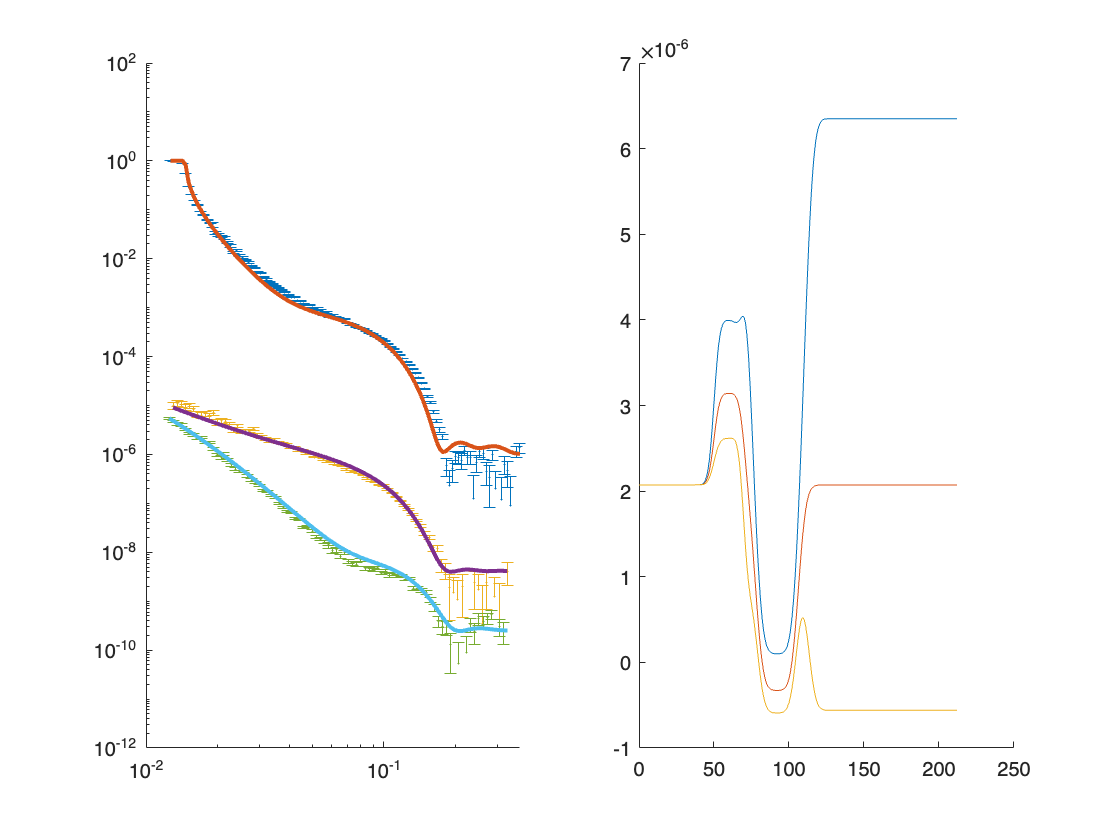

plotRefSLD(problem,results);

Our guess values were not too bad here. We can proceed directly to the Bayesian Analysis.....

controls.procedure = 'dream';

controls.nSamples = 25000;
controls.parallel = 'contrasts';
controls.adaptPCR = true

controls =   controlsClass with properties:

            parallel: 'contrasts'
           procedure: 'dream'
    calcSldDuringFit: 0
             display: 'iter'
           resamPars: [0.9000 50]
            nSamples: 25000
             nChains: 10
     jumpProbability: 0.5000
          pUnitGamma: 0.2000
       boundHandling: 'fold'
            adaptPCR: 1


Send this to RAT....

[problem,results] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________


Running DREAM

------------------ Summary of the main settings used ------------------


DREAMPar = struct with fields:
             d: 15
             N: 10
             T: 2500
      parallel: 0
           CPU: 1
        lambda: 0.5000
    pUnitGamma: 0.2000
           nCR: 3
         delta: 3
         steps: 50
          zeta: 1.0000e-12
       outlier: 'iqr'
      adaptPCR: 1
      thinning: 1
       epsilon: 0.0250
           ABC: 0
            IO: 0
        modout: 0
       restart: 0
          save: 0
             R: [10×10 double]


-----------------------------------------------------------------------

 DREAM:    0.1% [........................................]


 DREAM:  100.0% [****************************************]
Elapsed time is 15.496702 seconds.

Finished RAT ______________________________________________________________________________________________ 



Now plot our the results....

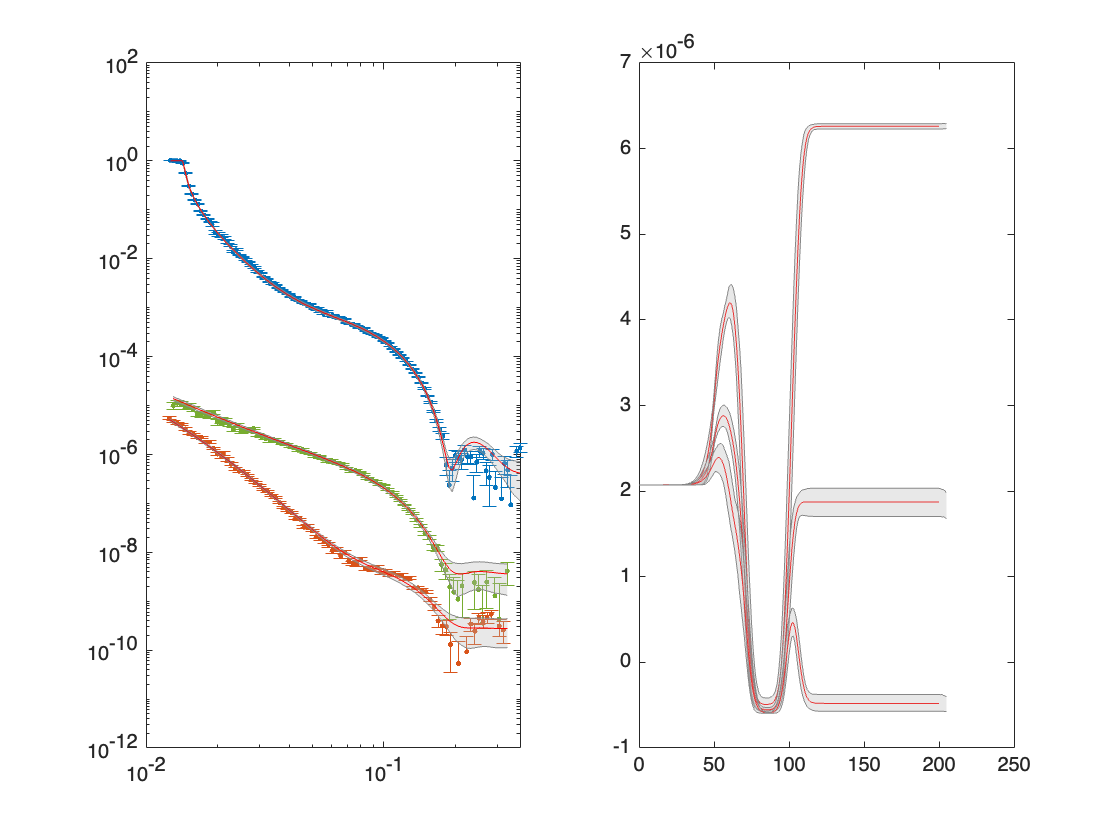

h1 = figure;    
bayesShadedPlot(problem,results,'fit','average','KeepAxes',true,'interval',65,'q4',false);

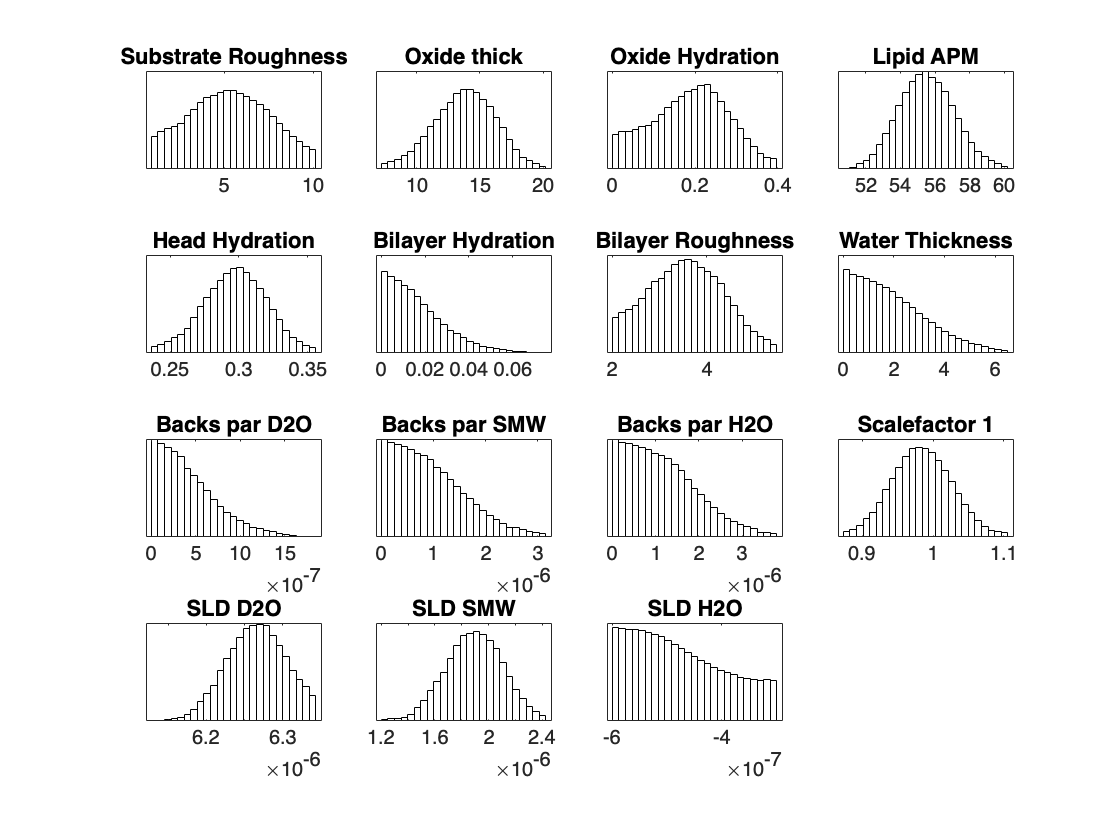

ans =   Axes (SLD H2O) with properties:

             XLim: [-6.0960e-07 -2.9040e-07]
             YLim: [0 4.7960e+06]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5422 0.1100 0.1566 0.1577]
            Units: 'normalized'

  Show all properties



h2 = figure;
plotHists(results,h2,'smooth',true)


h3 = figure

h3 =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


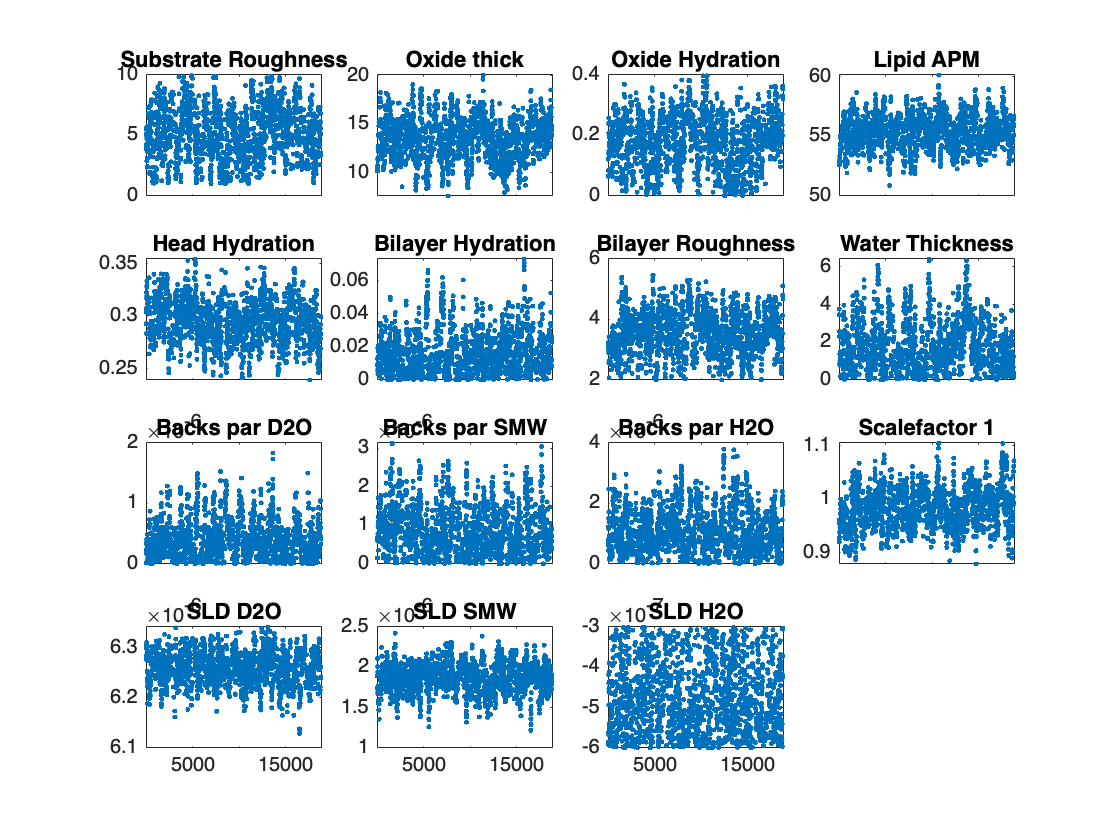

mcmcplot(results.chain,[],results.fitNames,'chainpanel');


h4 = figure

h4 =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


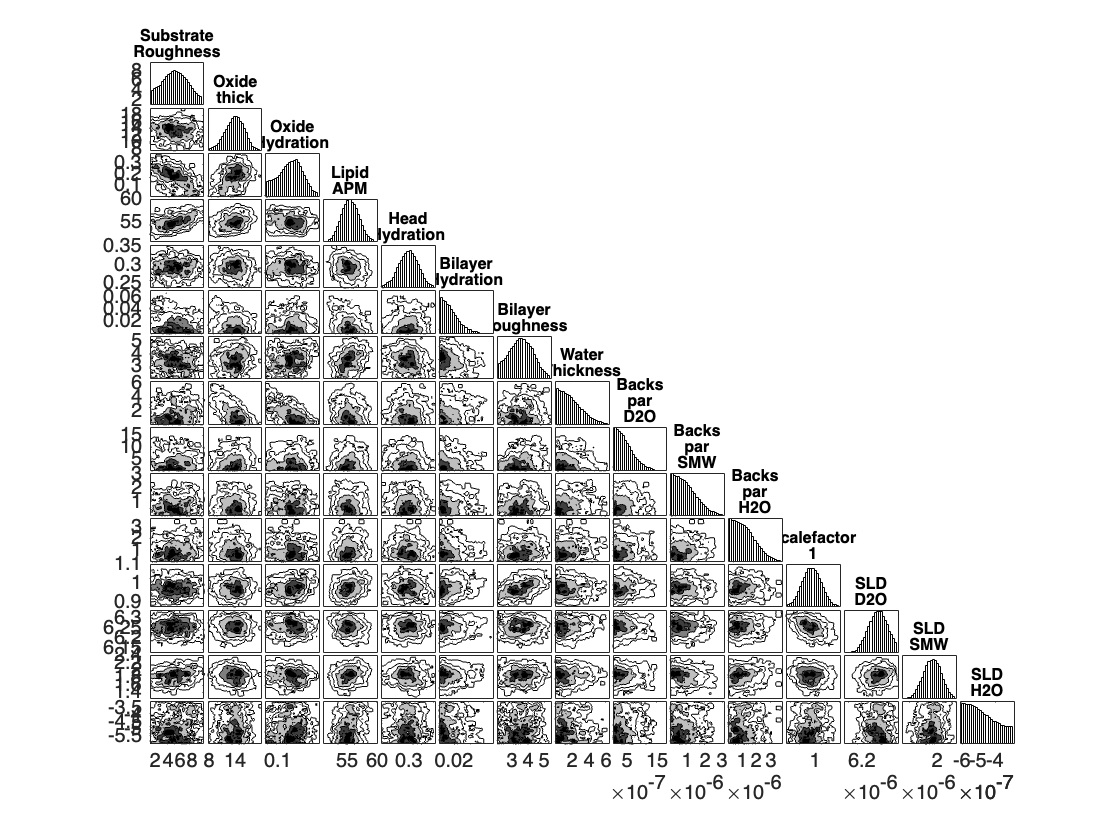

cornerPlot(results,h4,'smooth',false)

...and we're done.